load data\signal_2_hand_rail_pulse_responses.mat

x=Basic_reading_Machine_1_Vibro_1(:,2)';

fs=Basic_reading_Machine_1_Vibro_1_metadata.SamplingRate

fs = 25000

dt=1/fs

dt = 4.0000e-05


n=length(x)

n = 800000


t=(0:n-1).*dt;
t(end)

ans = 32.0000

Time Waveform (TW)    (high pass filter maye?)

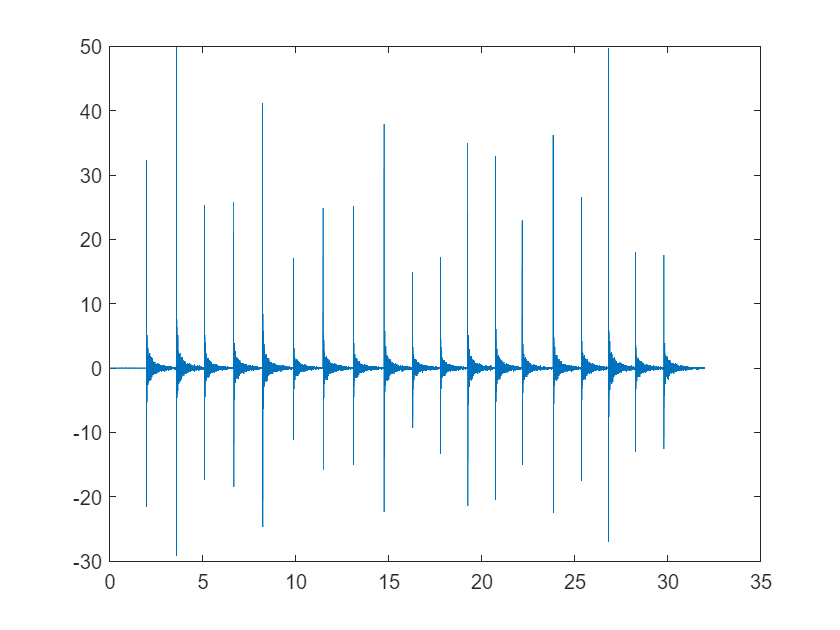

figure(1)
plot(t,x)



X=fft(x);
% X=ftt(x,2^19);
% n=2^19

mag=abs(X);
df=(fs/n)

df = 0.0313

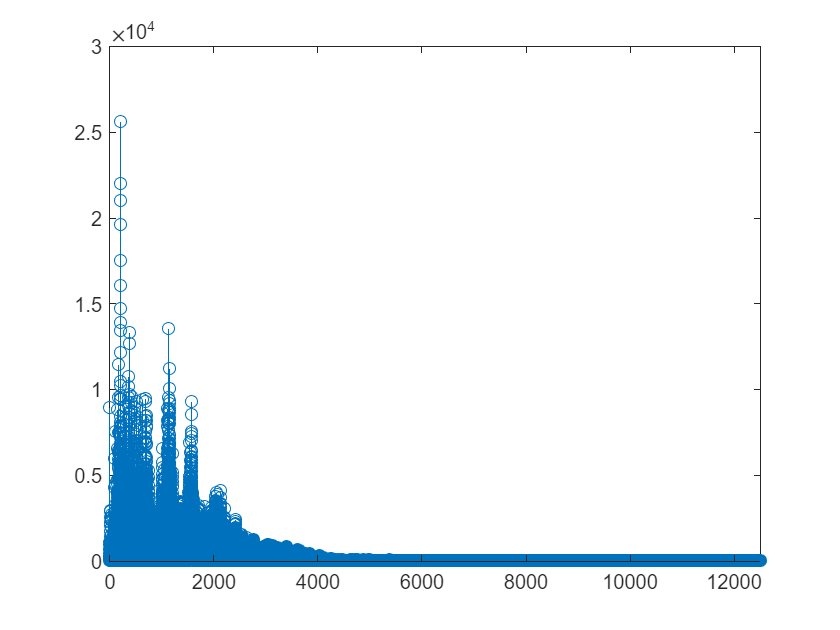

f=df*(0:n-1);
% figure
% subplot(2,1,1)
figure(2)
stem(f,mag')
xlim([0,fs/2])



% subplot(2,1,2)
% stem(f,mag')
% xlim([0,10])



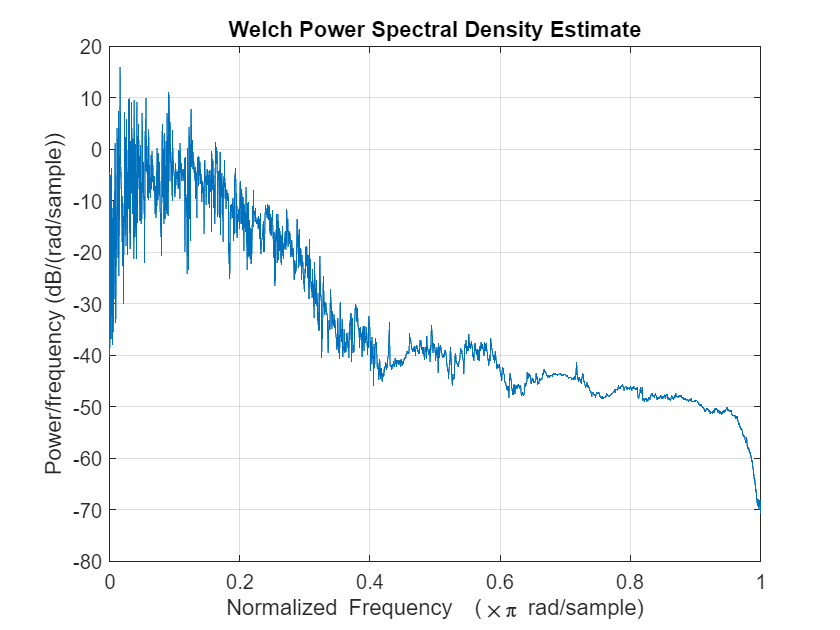

pwelch(x,fs)

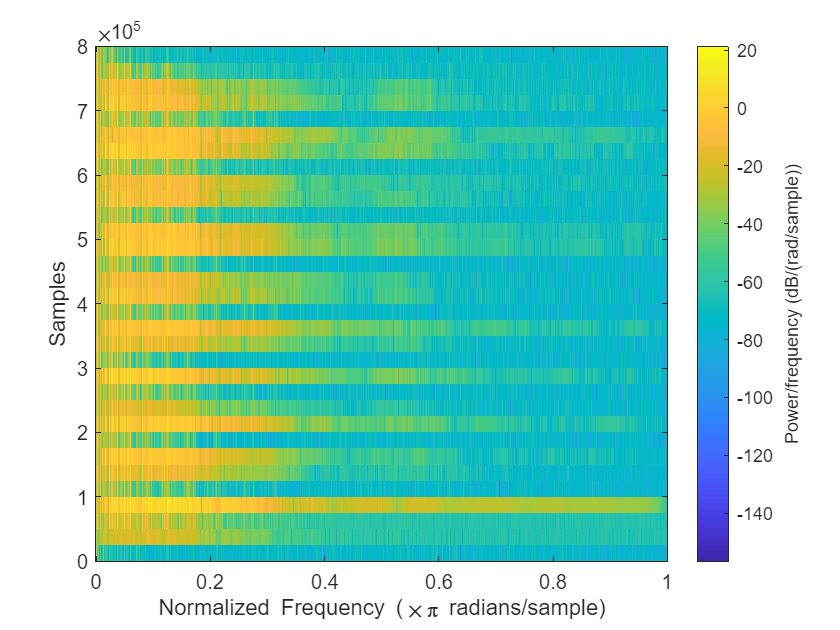

% spectrogram(x,fs)
spectrogram(x,fs,[0])

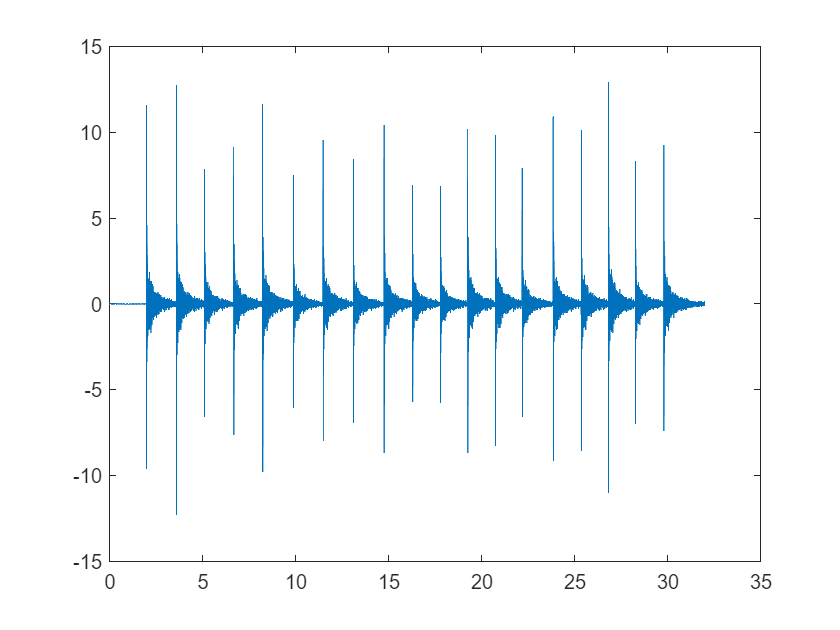


[x2,filter1]=lowpass(x,1,fs);
x3=x-x2;

fvtool(filter1)

plot(t,x2)

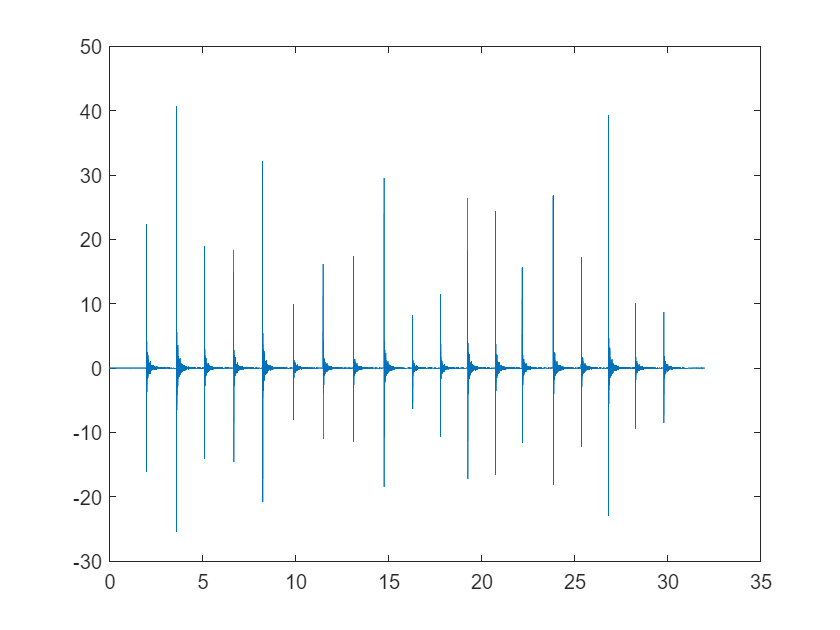

plot(t,x3)

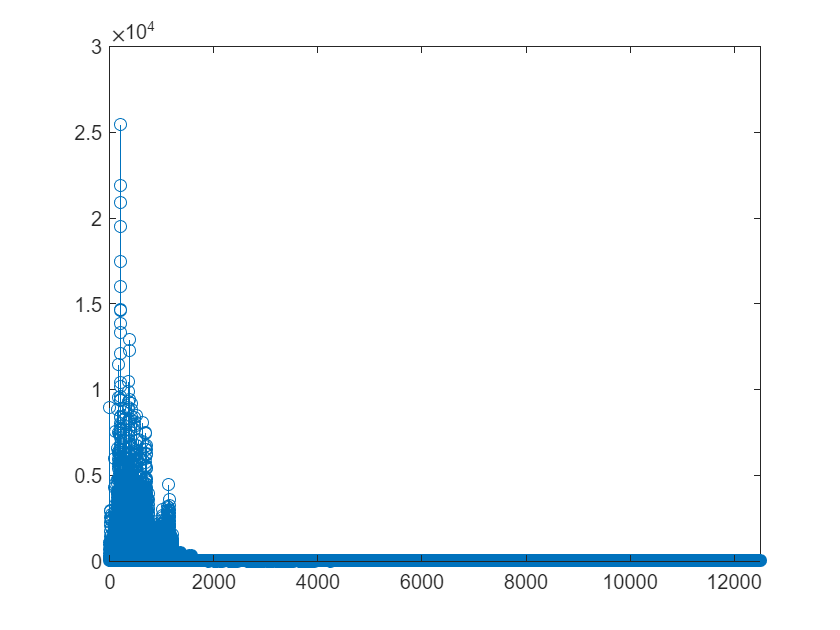


stem(f,abs(fft(x2)))
xlim([0,fs/2])

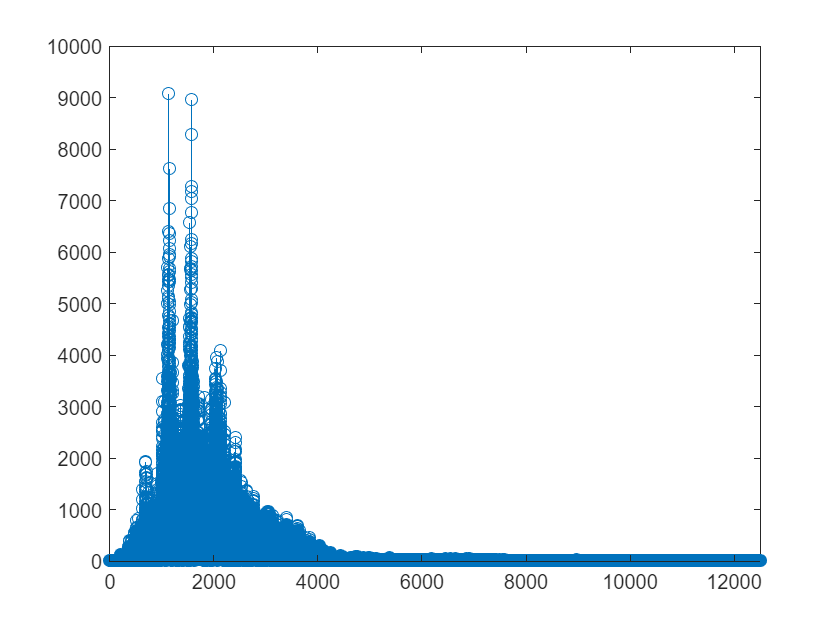

stem(f,abs(fft(x3)))
xlim([0,fs/2])

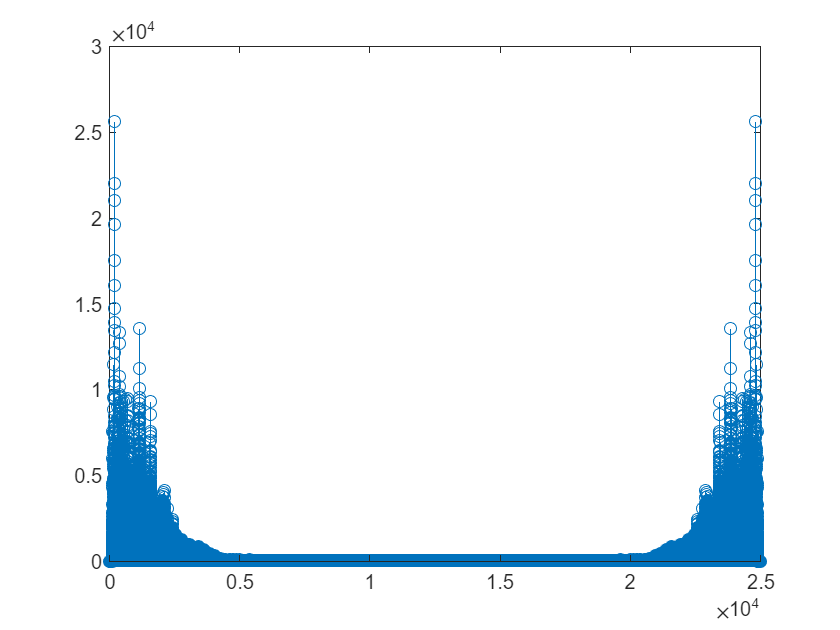


[x4,X4]=Filter_signal_HP(x,fs,100);
stem(f,abs(X4))